x=[2 5 5.4 7]

x =    2.000000000000000   5.000000000000000   5.400000000000000   7.000000000000000


y=[ 2 7 -3 15]

y =      2     7    -3    15


[Tabla] = Newtonint(x,y)

Tabla =    2.000000000000000   2.000000000000000                   0                   0                   0
   5.000000000000000   7.000000000000000   1.666666666666667                   0                   0
   5.400000000000000  -3.000000000000000 -24.999999999999979  -7.843137254901954                   0
   7.000000000000000  15.000000000000000  11.250000000000002  18.124999999999989   5.193627450980388


[pol] = Newtonor(x,diag(Tabla,+1))

pol = 1.0e+02 *

   0.051936274509804  -0.722441176470588   3.048240196078430  -3.602205882352939


syms p
f=p^3*pol(1)+p^2*pol(2)+p*pol(3)+pol(4)

$$f = \frac{2119\,p^{3}}{408}-\frac{24563\,p^{2}}{340}+\frac{1340630215936971\,p}{4398046511104}-\frac{24495}{68}$$

d=double(subs(f,p,0:0.01:10))

d = 1.0e+02 *

  -3.602205882352941  -3.571795672573530  -3.541529639411765  -3.511407471250000  -3.481428856470588  -3.451593483455882  -3.421901040588235  -3.392351216250000  -3.362943698823530  -3.333678176691176  -3.304554338235294  -3.275571871838236  -3.246730465882353  -3.218029808750000  -3.189469588823530  -3.161049494485295  -3.132769214117648  -3.104628436102942  -3.076626848823529  -3.048764140661765  -3.021040000000001  -2.993454115220588  -2.966006174705882  -2.938695866838236  -2.911522880000001  -2.884486902573530  -2.857587622941177  -2.830824729485295  -2.804197910588236  -2.777706854632354  -2.751351250000001  -2.725130785073530  -2.699045148235295  -2.673094027867648  -2.647277112352942  -2.621594090073530  -2.596044649411766  -2.570628478750001  -2.545345266470589  -2.520194700955883  -2.495176470588236  -2.470290263750001  -2.445535768823530  -2.420912674191177  -2.396420668235295  -2.372059439338236  -2.347828675882354  -2.323728066250001  -2.299757298823530  -2.

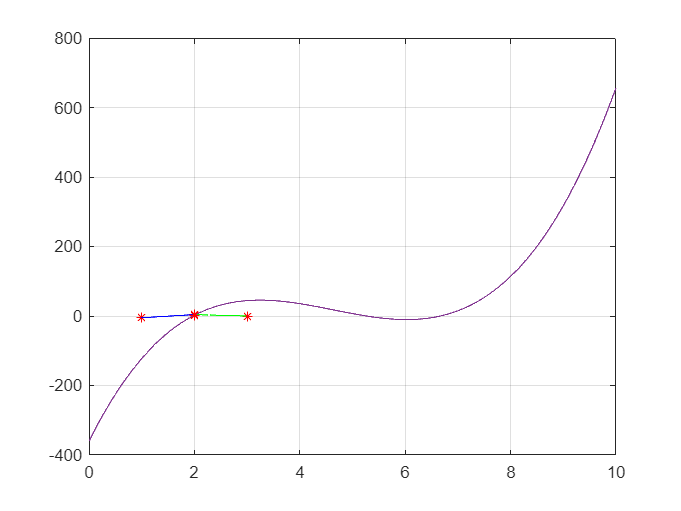

plot(0:0.01:10,d)
hold on
plot(2,double(subs(f,p,2)),"*r")
hold off

xn=[x 10];
yn=[y 8];
[tabla_n]=Newtonint(xn,yn)

tabla_n =    2.000000000000000   2.000000000000000                   0                   0                   0                   0
   5.000000000000000   7.000000000000000   1.666666666666667                   0                   0                   0
   5.400000000000000  -3.000000000000000 -24.999999999999979  -7.843137254901954                   0                   0
   7.000000000000000  15.000000000000000  11.250000000000002  18.124999999999989   5.193627450980388                   0
  10.000000000000000   8.000000000000000  -2.333333333333333  -2.952898550724639  -4.215579710144925  -1.176150895140664


[pol_n]=Newtonor(xn,diag(tabla_n,+1))

pol_n = 1.0e+02 *

  -0.011761508951407   0.280109548167093  -2.305540281329922   7.618762574595050  -8.048056265984648


error=tabla_n(end,end)*(xn(end)-xn(1))*(xn(end)-xn(2))*(xn(end)-xn(3))*(xn(end)-xn(4))

error =     -6.492352941176464e+02


x=[ 1 2 3]

x =      1     2     3


y=[-5 4 0]

y =     -5     4     0


xpol0=1:0.001:2;
xpol1=2:0.001:3;
[Tabla] = Spline(x,y,1)

Tabla =    9.000000000000000 -14.000000000000000
  -3.999999999999999  11.999999999999998


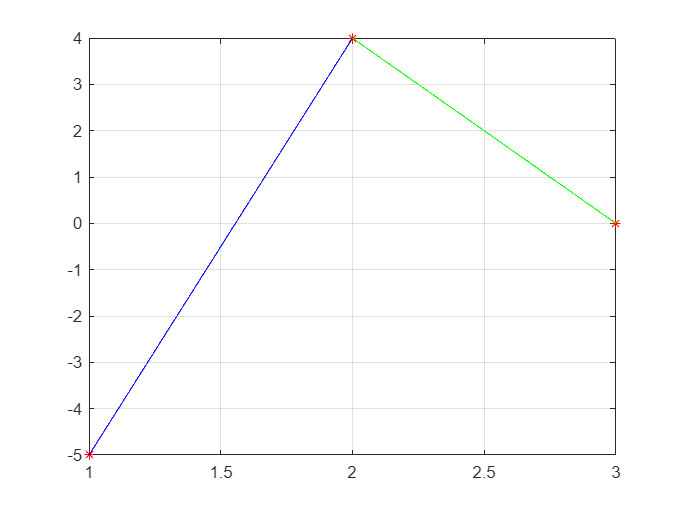

 p0=Tabla(1,1)*xpol0+Tabla(1,2);
 p1=Tabla(2,1)*xpol1+Tabla(2,2);
plot(x,y,'r*')
hold on
grid on
plot(xpol0,p0,'b',xpol1,p1,'g')

x=[3 3.6667 4.3333 5]

x =    3.000000000000000   3.666700000000000   4.333300000000000   5.000000000000000


y=[6.7472 10.7997 15.8063 21.7486]

y =    6.747200000000000  10.799700000000000  15.806300000000000  21.748600000000000


tabla=Newtonint(x,y)

tabla =    3.000000000000000   6.747200000000000                   0                   0                   0
   3.666700000000000  10.799700000000000   6.078446077696113                   0                   0
   4.333300000000000  15.806300000000000   7.510651065106508   1.074180595072673                   0
   5.000000000000000  21.748600000000000   8.913004349782515   1.051791258288463  -0.011194668392105


error=tabla(end,end)*(x(end)-x(1))*(x(end)-x(2))*(x(end)-x(3))*(x(end)-x(4))

error =      0


x=[1 1.1 1.2]

x =     1.0000    1.1000    1.2000


y=[3.21 3.64 4.11]

y =     3.2100    3.6400    4.1100


[Tabla] = Spline(x,y,3)

Tabla =    10.0000  -30.0000   34.2000  -10.9900
  -10.0000   36.0000  -38.4000   15.6300
